clear
close all hidden
path2savefig = "C:\Users\SA13\Desktop\ZX MATLAB\src\data\Investigations\MinMax Investigation";
load(fullfile(path2savefig,"summaryTable.mat"))
VARS = ["INLETTEMP" "OUTLETTEMP" "TEMPDIFF" "GENFREQ" "GENVOLTAGE" "VHZRATIO"];

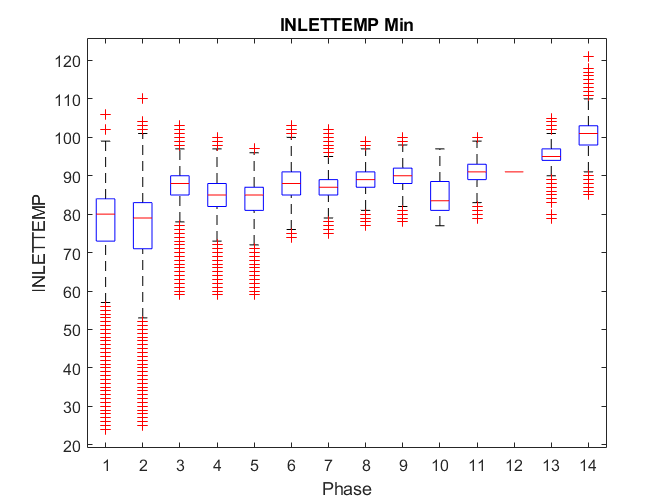

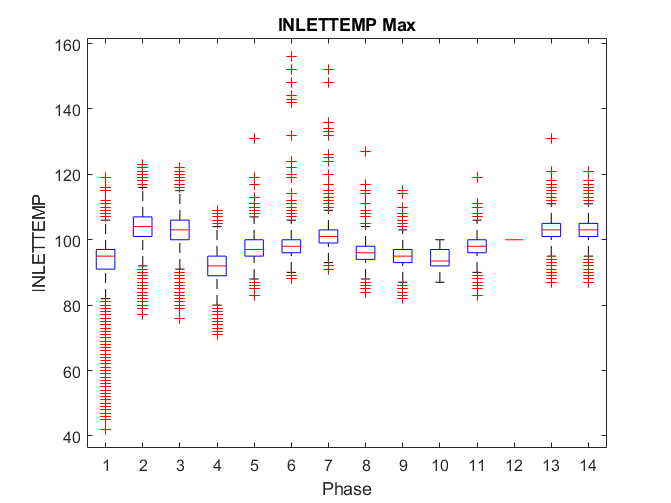

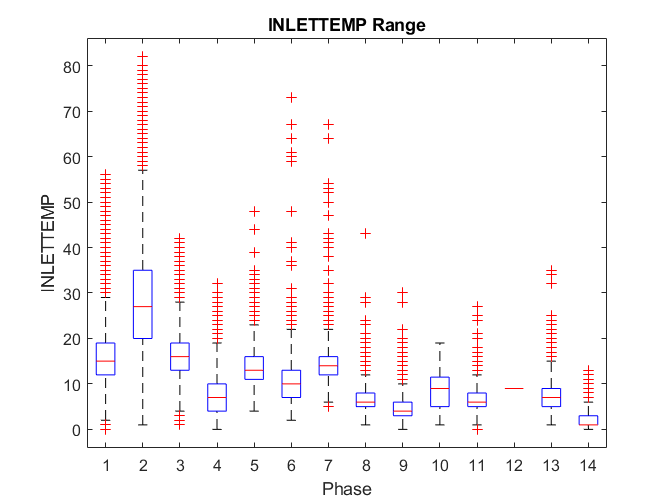

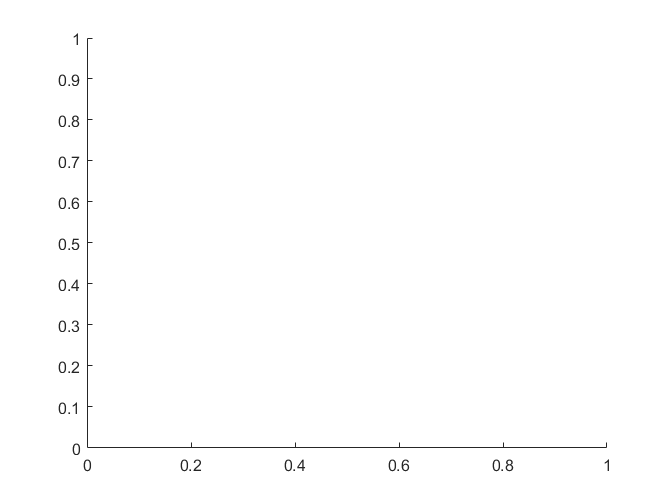

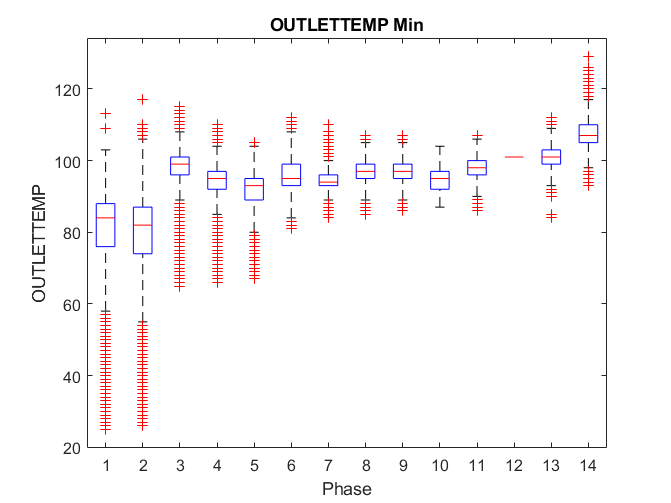

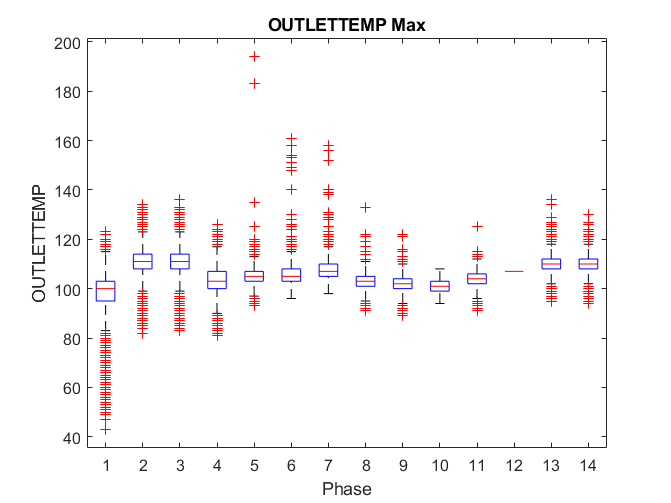

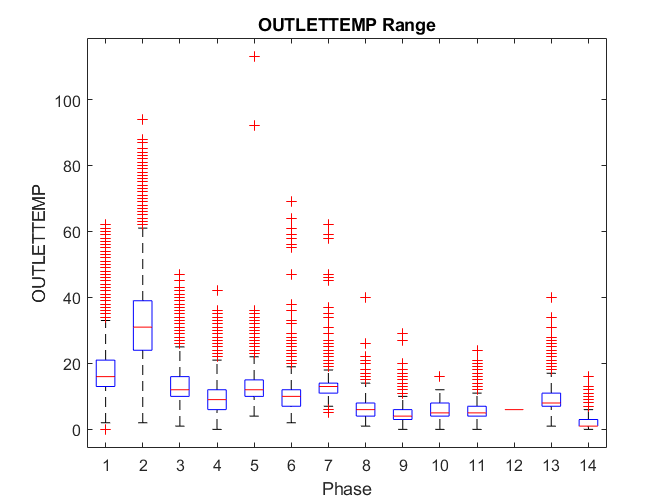

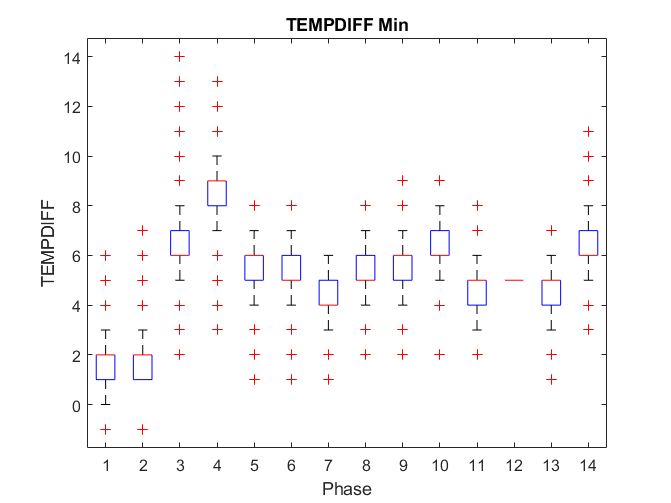

for genVar = 1:numel(VARS)
    clearvars -except path2savefig summaryTable VARS genVar
    close all hidden
    var = summaryTable.(VARS(genVar))';%cell array
    
    for tbl = 1:numel(var)
        summary = var{tbl};
        try
            minMatrix = padcat(minMatrix, summary.Min);
        catch
            minMatrix = summary.Min;
        end
        
        try
            maxMatrix = padcat(maxMatrix, summary.Max);
        catch
            maxMatrix = summary.Max;
        end
        
        try
            rangeMatrix = padcat(rangeMatrix, summary.Max - summary.Min);
        catch
            rangeMatrix = summary.Max - summary.Min;
        end
    end
    
    hold off
    figure(genVar)
    boxplot(minMatrix)
    pltTitle = VARS(genVar) + " Min";
    title(pltTitle)
    xlabel("Phase")
    ylabel(VARS(genVar))
%     saveas(genVar, fullfile(path2savefig, pltTitle + ".png"))
    
    
    figure(genVar+1)
    boxplot(maxMatrix)
    pltTitle = VARS(genVar) + " Max";
    title(pltTitle)
    xlabel("Phase")
    ylabel(VARS(genVar))
%     saveas(genVar+1, fullfile(path2savefig, pltTitle + ".png"))
    
    figure(genVar+2)
    boxplot(rangeMatrix)
    pltTitle = VARS(genVar) + " Range";
    title(pltTitle)
    xlabel("Phase")
    ylabel(VARS(genVar))
%     saveas(genVar+2, fullfile(path2savefig, pltTitle + ".png"))

end

min(summaryTable.GENFREQ{1}.Max)

ans = 382

function padded = padcat(a,b)
    % where a and b are 1D or 2D matrices
    [am, an] = size(a);
    [bm, bn] = size(b);
    
    if am < bm
        padLength = bm - am;
        padBreadth = an;
        a = [a; NaN(padLength,padBreadth)];
    elseif bm < am
        padLength = am - bm;
        padBreadth = bn;
        b = [b; NaN(padLength,padBreadth)];        
    end
    
    padded = [a b];
end